% This is a generic program to plot transient data from experiment-5
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Date: August 6th, 2020
% Dr. Vibhav Durgesh
% Rev 0.0
% User has to provide appropriate information - see beginning of code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
close all
clc

## File name with correct directory location

fname = ('../Data/TimeSeriesFlowRate_VoltageData2.dat'); % Reading data from the stored file
fid = fopen(fname, 'r'); % Openning file to read the data
line1 = fgetl(fid);
data = fscanf(fid,'%f \n', [3 inf]);
time = data(1,:);
voltage = data(2,:) - 2.35068885; % Subtracting the zero flow case data
flowrate = data(3,:);
fclose(fid);

## Generating figure with specific size

figure (1)
set(gcf,'unit','inches','position',[0.50 0.50 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data creating left y-axis

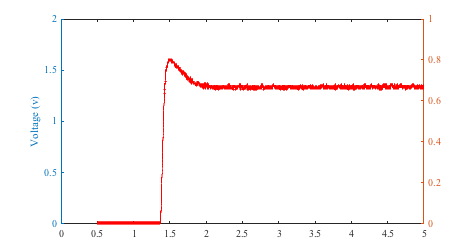

yyaxis left
plot(time(500:5000),voltage(500:5000),'ro-','markersize',1,'markerfacecolor','r');hold on
ylabel('Voltage (v)')

## Plotting data creating right y-axis

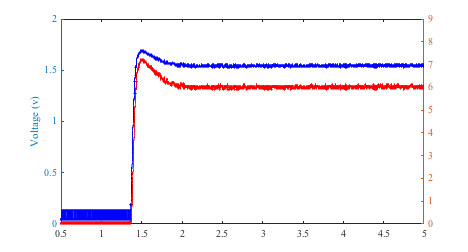

yyaxis right
plot(time(500:5000),flowrate(500:5000),'bo-','markersize',1,'markerfacecolor','b');hold on
xlim([0.5 5])
ylim([0 9])

## Setting labels

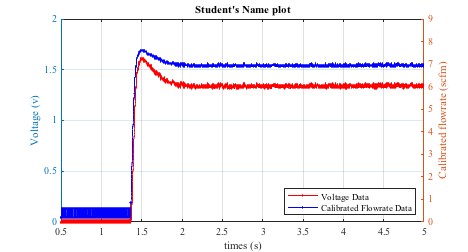

xlabel('times (s)')
ylabel('Calibrated flowrate (scfm)')
grid on
legend('Voltage Data','Calibrated Flowrate Data','location','Southeast')
title('Student''s Name plot')

## Saving the files in png and pdf format

figName = ['../Figures/Student_Name_Exp05_Part2'];
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'Papersize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')